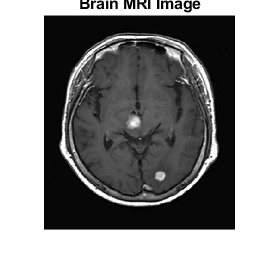

I=imread('C:\Users\Falcon\Desktop\assignments\MATLAB/brain3.png');
figure, 
imshow(I); title('Brain MRI Image');

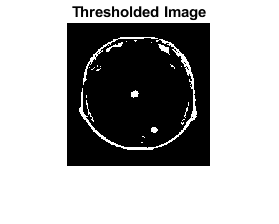

I = imresize(I,[200,200]);
I= im2gray(I);
I= imbinarize(I,.6);
figure, 
imshow(I);title('Thresholded Image');

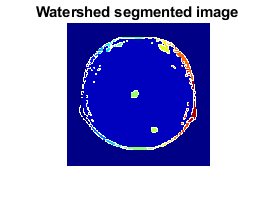

hy = fspecial('sobel');
hx = hy';
Iy = imfilter(double(I), hy, 'replicate');
Ix = imfilter(double(I), hx, 'replicate');
gradmag = sqrt(Ix.^2 + Iy.^2);
L = watershed(gradmag);
Lrgb = label2rgb(L);
figure, 
imshow(Lrgb), title('Watershed segmented image ')

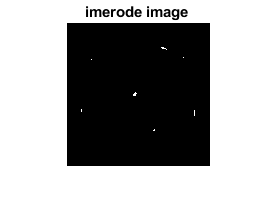

se = strel('disk', 3);
Ie = imerode(I, se);
figure,
imshow(Ie), title('imerode image ')

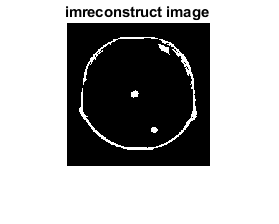

Iobr = imreconstruct(Ie, I);
figure,
imshow(Iobr), title('imreconstruct image ')

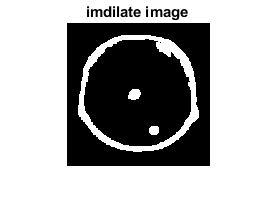

Iobrd = imdilate(Iobr, se);
figure,
imshow(Iobrd), title('imdilate image ')

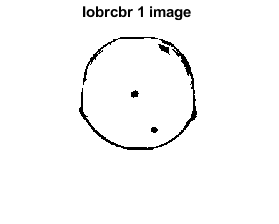

Iobrcbr = imreconstruct(imcomplement(Iobrd), imcomplement(Iobr));
imshow(Iobrcbr), title('Iobrcbr 1 image ')

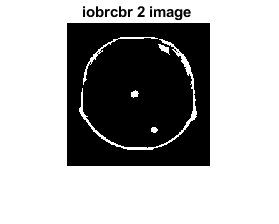

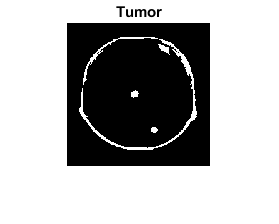

Iobrcbr = imcomplement(Iobrcbr);
imshow(Iobrcbr), title('iobrcbr 2 image ')
figure, 
imshow(Iobrcbr), title('Tumor')